# Control Invariance using MPT

This script requires the MPT Toolbox which you can find at [https://www.mpt3.org/](https://www.mpt3.org/)

clear
close all

## Double Integrator System

Define double integrator dynamics

Ts = 0.1

Ts = 0.1000

A = [1, Ts; 0 1];
B = [Ts^2/2; Ts];

with state and input constraints on the absolute value

absxmax = [1 ; 1];
absumax = 0.1;

## Control Invariant Set Computation

First we translate the system description into the MPT framework

system = LTISystem('A', A, 'B', B);
system.x.min = -absxmax

LTISystem with 2 states, 1 input, 0 outputs


system.x.max = absxmax;
system.u.min = -absumax;
system.u.max = absumax;

The command `system.invariantSet() `computes the resulting control invariant set

InvSet = system.invariantSet()

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...
Iteration 13...
Iteration 14...
Iteration 15...
Iteration 16...
Iteration 17...
Iteration 18...
Iteration 19...
Iteration 20...
Iteration 21...
Iteration 22...
Iteration 23...
Iteration 24...
Iteration 25...
Iteration 26...
Iteration 27...
Iteration 28...
Iteration 29...
Iteration 30...
Iteration 31...
Iteration 32...
Iteration 33...
Iteration 34...
Iteration 35...
Iteration 36...
Iteration 37...
Iteration 38...
Iteration 39...
Iteration 40...
Iteration 41...
Iteration 42...
Iteration 43...
Iteration 44...
Iteration 45...
Iteration 46...
Iteration 47...
Iteration 48...
Iteration 49...
Iteration 50...
Iteration 51...
Iteration 52...
Iteration 53...
Iteration 54...
Iteration 55...
Iteration 56...
Iteration 57...
Iteration 58...
Iteration 59...
Iteration 60...
Iteration 61...
Iteration 62...
Iteration 63...
I

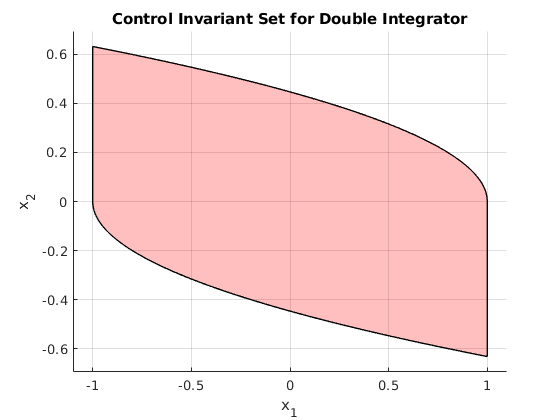

plot(InvSet), alpha(0.25), title('Control Invariant Set for Double Integrator'), xlabel('x_1'), ylabel('x_2')

## Approximate Control Invariance by Specifying Control Law

Control invariant set computations are computationally very expensive and can only be carried out for very small systems. One can conservatively approximate the control invarant set by specifying a control law and solving the simpler invariance problem.

We first define an LQR controller

Q = eye(2);
R = 1000;
K = -dlqr(A,B,Q,R);

Which results in a closed loop autonomous system

systemLQR = LTISystem('A', A+B*K);

We express the constraint $|u| \leq |u|_\max$ in terms of the state as$|Kx| \leq |u|_\max$ resulting in polytopic state constraints

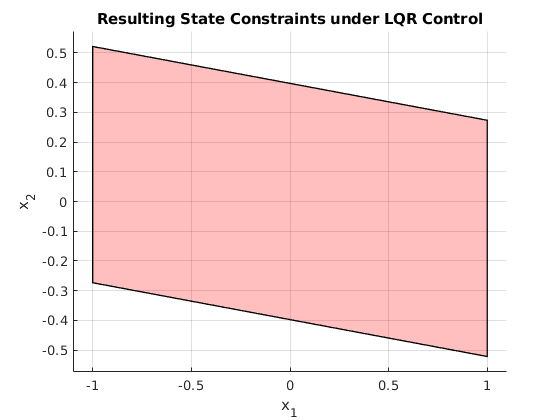

Xp = Polyhedron('A',[eye(2); -eye(2); K; -K], 'b', [absxmax;absxmax; absumax;absumax]);
figure(2)
Xp.plot(), alpha(0.25), title('Resulting State Constraints under LQR Control'), xlabel('x_1'), ylabel('x_2')

We add this constraint in MPT framework

systemLQR.x.with('setConstraint');
systemLQR.x.setConstraint = Xp;

Since `systemLQR` is an autonomous system, the command `system.invariantSet()` now computes the simpler invariant set

InvSetLQR = systemLQR.invariantSet()

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...
Iteration 13...
Iteration 14...
Iteration 15...
Iteration 16...
Iteration 17...
Iteration 18...
Iteration 19...
Iteration 20...
Iteration 21...
Iteration 22...
Iteration 23...
Iteration 24...
Iteration 25...
Iteration 26...
Iteration 27...
Iteration 28...
Iteration 29...
Iteration 30...
Iteration 31...
Iteration 32...
Iteration 33...
Iteration 34...
Iteration 35...
Iteration 36...
Iteration 37...
Iteration 38...
Iteration 39...
Iteration 40...
Iteration 41...
Iteration 42...
Iteration 43...
Iteration 44...
Iteration 45...
Iteration 46...
Iteration 47...
Iteration 48...
Iteration 49...
Iteration 50...
Iteration 51...
Iteration 52...
Iteration 53...
Iteration 54...
Iteration 55...
Iteration 56...
Iteration 57...
Iteration 58...
Iteration 59...
Iteration 60...
Iteration 61...
Iteration 62...
Iteration 63...
I

Since it is a conservative approximation, this set will always be contained in the control invariant set

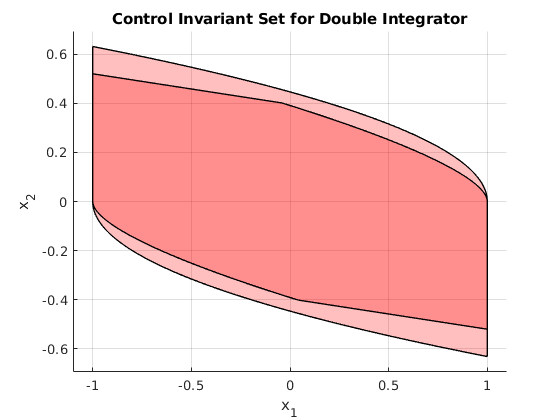

figure(1)
hold on
InvSetLQR.plot(), alpha(0.25)

## Triple Integrator System

To illustrate the scalability of the computations we consider now a triple integrator system and repeat the computations

A = [1, Ts, Ts^2/2; 0, 1, Ts; 0 0 1];
B = [Ts^3/6; Ts^2/2; Ts];
nx = 3;
absxmax = ones(nx,1);
absumax = 0.1;

## Approximate Control Invariance by Specifying Control Law

When specifying the control law the computations are still reasonably fast.

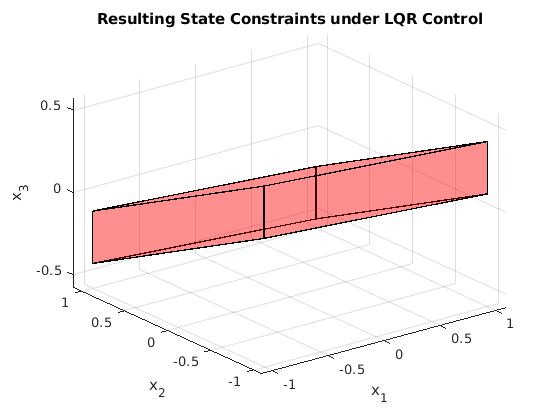

Q = eye(nx);
R = 1000;
K = -dlqr(A,B,Q,R);

Ak = A+B*K;
systemLQR = LTISystem('A', A+B*K);
Xp = Polyhedron('A',[eye(nx); -eye(nx); K; -K], 'b', [absxmax;absxmax; absumax;absumax]);
figure(2)
Xp.plot(),  alpha(0.25), title('Resulting State Constraints under LQR Control'), xlabel('x_1'), ylabel('x_2'), zlabel('x_3')


systemLQR.x.with('setConstraint');
systemLQR.x.setConstraint = Xp;
InvSetLQR = systemLQR.invariantSet()

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...
Iteration 13...
Iteration 14...
Iteration 15...
Iteration 16...
Iteration 17...
Iteration 18...
Iteration 19...
Iteration 20...
Iteration 21...
Iteration 22...
Iteration 23...
Iteration 24...
Iteration 25...
Iteration 26...
Iteration 27...
Iteration 28...
Iteration 29...
Iteration 30...
Iteration 31...
Iteration 32...
Iteration 33...
Iteration 34...
Iteration 35...
Iteration 36...
Iteration 37...
Iteration 38...
Iteration 39...
Iteration 40...
Iteration 41...
Iteration 42...
Iteration 43...
Iteration 44...
Iteration 45...
Iteration 46...
Iteration 47...
Iteration 48...
Iteration 49...
Iteration 50...
Iteration 51...
Iteration 52...
Iteration 53...
Iteration 54...
Iteration 55...
Iteration 56...
Iteration 57...
Iteration 58...
Iteration 59...
Iteration 60...
Iteration 61...
Iteration 62...
Iteration 63...
P

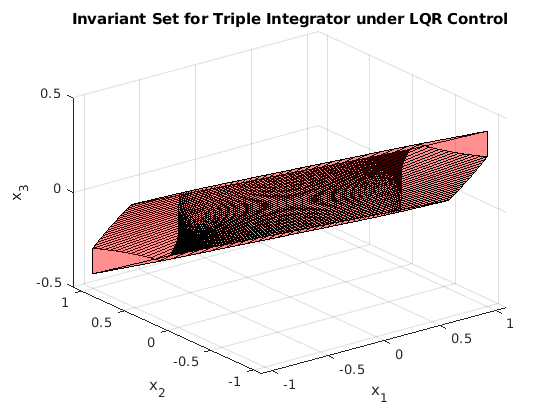

InvSetLQR.plot(), alpha(0.25), title('Invariant Set for Triple Integrator under LQR Control'), xlabel('x_1'), ylabel('x_2'), zlabel('x_3')

## Control Invariant Set Computation

Already for this system size the computation of the control invariant set is computationally too demanding

system = LTISystem('A', A, 'B', B);
system.x.min = -absxmax

LTISystem with 3 states, 1 input, 0 outputs


system.x.max = absxmax;
system.u.min = -absumax;
system.u.max = absumax;
InvSet = system.invariantSet()

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...
Iteration 9...
Iteration 10...
Iteration 11...
Iteration 12...


hold on
InvSet.plot(), alpha(0.25)